clc
clear
close all
set(0, 'DefaultLineLineWidth', 2);
set(0, 'defaultAxesFontSize', 12)
set(0, 'defaultAxesTickLabelInterpreter','latex');
set(0, 'defaultlegendInterpreter','latex')

## The system 

We will consider a LTI system of the form:


$$\begin{cases} \underset{n \text{ x } 1}{x_{t+1}} = \underset{ n \text{ x } n}{A} \cdot \underset{n \text{ x } 1}{x_t} + \underset{n \text{ x } m}{B} \cdot  \underset{m \text{ x } 1}{u_t} + \underset{n \text{ x } l}{K} \cdot \underset{l \text { x } 1}{e_t} \quad \quad (1)\\ \underset{l \text{ x } 1}{y_t} = \underset{l \text{ x } n}{C} \cdot  \underset{n \text{ x } 1}{x_t} + \underset{l \text{ x } m}{D} \cdot \underset{m \text{ x } 1}{u_t} + \underset{l \text{ x } 1}{e_t} \quad \quad \quad \ (2) \end{cases}$$


where 

- the inputs $u_t \in \mathbb{R}^m  \ \Leftrightarrow \ m =$ number of inputs, 

- the outputs $y_t \in \mathbb{R}^l \ \Leftrightarrow \ l =$ number of outputs,

- the states $x_t \in \mathbb{R}^n \ \Leftrightarrow n =$ number of states.

- the noise sequence $e_t$ is supposed to be $\sim WN(0; \Sigma_e)$ with $\Sigma_e = \mathbb{E}[e_k e_k^T]$ and $\Sigma_{ij} = \mathbb{E}[e_i e _k^T]=0 \text{ for } i \ne k$

- $N_s =$ number of samples

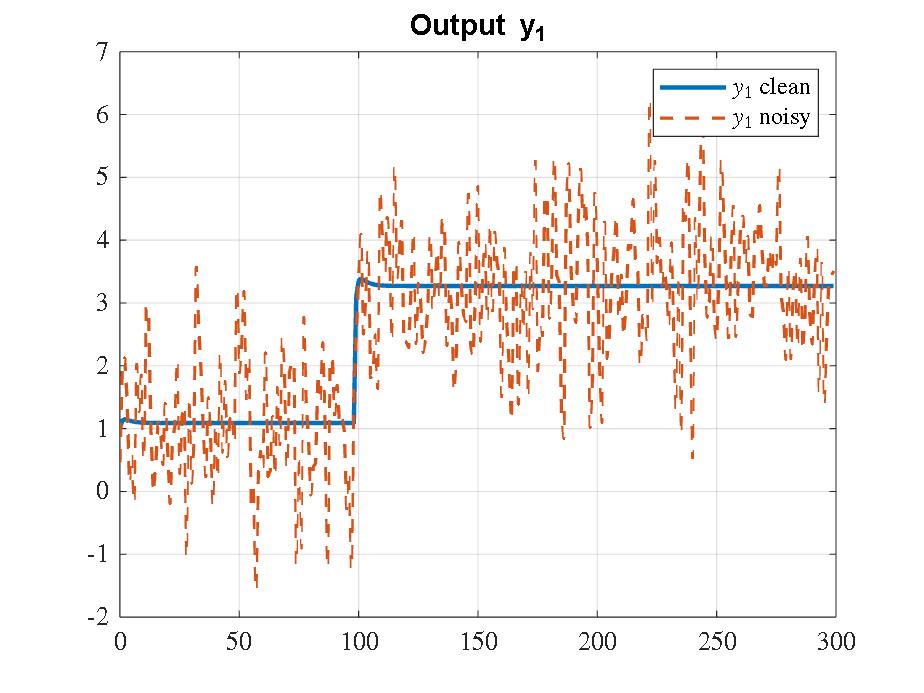

m = 3;
l = 2;
n = 2; 
Ns = 300;
Ts = 1;                                     % sampling time
t = (0:Ns-1) * Ts;                          % time of sampling
A = [0.7  0; 0  0.3];                       % states matrix [n x n]
B = [-0.1  0.2  0.6; 0.9 -0.5 -0.4];        % inputs matrix [n x m]
C = [0.5  0.2; 0.6 -0.8];                   % outputs matrix [l x n]
D = [1 0 0; 0 0 0];                         % [l x m]
K = [1 0; 0 1; 0 0];                        % [n x l] 

rng(42);
e = randn(Ns, l);
x = zeros (Ns, n);
y = zeros(Ns, l);
u = zeros(Ns,m);
u(1:99,1)=1; u(100:Ns,1)=3; 

y_clean = zeros(Ns, l, m);
sys = cell(m,1); 
for j = 1:m
    U = u(:,j);                                 % matrice di tutti gli ingressi
    sys{j} = ss(A, B(:,j), C, D(:,j), 1);       % calcolo il modello degli stati del sistema
    y_clean(:,:,j) = lsim(sys{j}, U, t);        % calcolo la y senza il rumore
end
y_noise = y_clean + e;                          % calcolo la y con il rumore

% Grafico y_1
figure;
plot(t, y_clean(:,1,1), 'LineWidth', 2); hold on;
plot(t, y_noise(:,1,1), '--', 'LineWidth', 1.5);
grid on;
legend('$y_1$ clean','$y_1$ noisy','Interpreter', 'latex');
title('Output y_1');

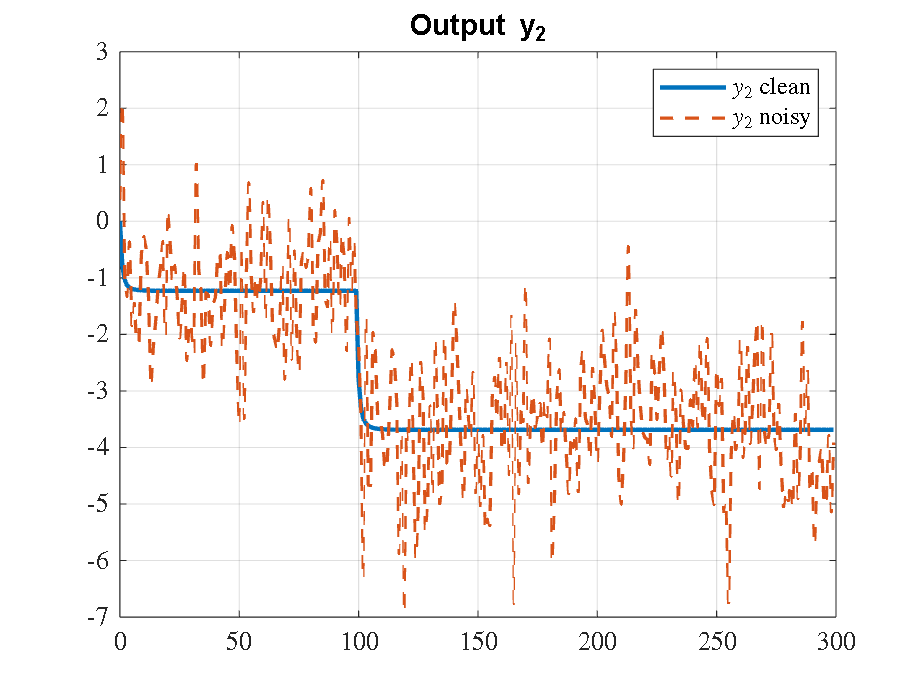


% Grafico y_2
figure;
plot(t, y_clean(:,2,1), 'LineWidth', 2); hold on;
plot(t, y_noise(:,2,1), '--', 'LineWidth', 1.5);
grid on;
legend('$y_2$ clean','$y_2$ noisy','Interpreter', 'latex');
title('Output y_2');

## Matrix input-output equations


$$Y_f = \Gamma_N X_f + H_N U_f + H_N^S E_f \quad \quad (3)$$



$$Y_p = \Gamma_M X_p + H_M U_p + H_M^S E_p \quad \quad (4)$$



$$\underset{mM \text{ x } j}{U_p} = \left( \begin{array}{c} u_1 & u_2 & ... & u_j \\ u_2 & u_3 & ... & u_{j+1} \\ ... & ... & ... & ... \\ u_M & u_{M+1} & ... & u_{j+M-1} \end{array} \right) \quad \quad (5)$$



$$\underset{mN \text{ x } j}{U_f} = \left( \begin{array}{c} u_{M+1} & u_{M+2} & ... & u_{M+j} \\ u_{M+2} & u_{M+3} & ... & u_{M+j+1} \\ ... & ... & ... & ... \\ u_{M+N} & u_{M+N+1} & ... & u_{M+N+j} \end{array} \right) \quad \quad (6)$$


In a similar way, we define the block Hankel matrices $\underset{lM \text{ x } j}{Y_p}, \quad \underset{lN \text{ x }j}{Y_f}, \quad  \underset{lM \text{ x } j}{E_p}, \quad \underset{lN \text{ x }j}{E_f,} $

$j$ must be much larger (tipically 100 times) than $N,M$: $j \ge 100 \cdot \max(N,M)$ but $N_s = M+N+j$


$$\underset{(m+l)M \text{ x } j}{W_p} \triangleq \left( \begin{array}{c} Y_p \\ U_p \end{array} \right)$$


The past and the future state sequences are definited as


$$\underset{nM \text{ x } j}{X_p} = (x_1 \quad x_2 \quad ... \quad x_j)$$



$$\underset{nN \text{ x } j}{X_f} = (x_{M+1} \quad x_{M+2} \quad ... \quad x_{M+j})$$


$\underset{ql \text{ x } n}{\Gamma_q} = \left( \begin{array}{c} C \\ CA \\ ... \\ C A^{q-1} \end{array} \right)$ , $\quad \underset{ql \text{ x } qm}{H_q}= \left( \begin{array}{c} D & 0 & ... & 0 \\ CB & D & ... & 0 \\ ... & ... & ... & ... \\ C A^{q-2}B & CA^{q-3} B & ... & D \end{array} \right)$, $\quad \underset{ql \text{ x } ql}{H_q^S}= \left( \begin{array}{c} I_l & 0 & ... & 0 \\ CK & I_l & ... & 0 \\ ... & ... & ... & ... \\ C A^{q-2}K & CA^{q-3} K & ... & I_l \end{array} \right)$ 

where $q \in \mathbb{N}_0$, $\Gamma_q$ is the extended observability matrix, $H_q$ and $H_q^S$ are the Toeplitz matrices containing the impulse response of the system to the deterministic input $u_k$ and to the stochastic input $e_k$ respectively.

%% hhhh

## Plot

%{
figure
h = biplot(Vq, 'scores', scores, 'varlabels', vbls, ...
        'ObsLabels', states, 'MarkerSize', 15, 'Markersize', 20,... 
        'LineWidth', 2);
for t = 1 : 1 : 8
    h(t).Color = [255 165 0]/255; 
end
for t = 9 : 1: 12
    h(t).FontWeight = 'bold';  
    h(t).FontSize = 14;  
    h(t).Color = [255 165 0]/255;
end
for t = 13 : 1: length(h)
    h(t).Color = [135 206 255]/255;
    h(t).MarkerSize = 22;
end
%}

## Add names of states on the points

The signs of the principal components are arbitrary, but BIPLOT enforces the convention that the largest coefficient for each PC (loadings vectors) is positive. This tends to put the largest variable vectors in the top and right halves of the plot. Since BIPLOT also plots the points for each observation according to this convention, the label positions need to be computed accordingly. That's what this code does.

%{
[dum, maxind] = max(abs(Vq), [], 1);
colsign = sign(  [Vq(maxind(1), 1)    Vq(maxind(2), 2)]  ); 
scores_normalized = (scores ./ max(abs(scores(:)))) .* repmat(colsign, N, 1);

delta_x = .01 * diff( get(gca,'XLim') );
delta_y = .01 * diff( get(gca,'YLim') );
t = text(scores_normalized(:, 1) + delta_x, scores_normalized(:, 2) + delta_y, states);
for t = 1 : 1 : length(t)
    t(t).FontSize = 12;
    t(t).Color = [0 154 205]/255;
    t(t).FontName = 'Courier';
    t(t).FontWeight = 'bold';
end
%}

## Plot reconstructed data vs. original data

%{
reconstructed = scores * Vq'; % reconstruct 4-dimensional data

figure
plot(Z(:, 1), 'bo-', 'linewidth', 2); hold on
plot(reconstructed(:, 1), 'rx--', 'linewidth', 2);
grid on;
xlabel('Data number'); ylabel('Data value');
legend('Original', 'Reconstructed');
xlim([1, 50])
%}
